%Assignment 1.1

Ad = load("Ad.mat")

Ad = struct with fields:
    Ad: [61×3 double]


Ad2 = load("Ad2.mat")

Ad2 = struct with fields:
    Ad2: [61×3 double]


L = 400:5:700;

Ad1 = Ad.Ad(:,:)

Ad1 =     0.0004    0.0004    0.0232
    0.0002    0.0003    0.0259
    0.0003    0.0003    0.0283
    0.0002    0.0002    0.0300
    0.0002    0.0002    0.0318
    0.0002    0.0002    0.0334
    0.0002    0.0002    0.0350
    0.0001    0.0001    0.0363
    0.0001    0.0002    0.0378
    0.0001    0.0002    0.0399


Ad2 = Ad2.Ad2(:,:)

Ad2 =     0.0001    0.0001    0.0005
    0.0002    0.0002    0.0010
    0.0005    0.0003    0.0026
    0.0018    0.0013    0.0112
    0.0031    0.0026    0.0223
    0.0032    0.0034    0.0290
    0.0032    0.0040    0.0332
    0.0029    0.0044    0.0344
    0.0024    0.0048    0.0356
    0.0021    0.0053    0.0384


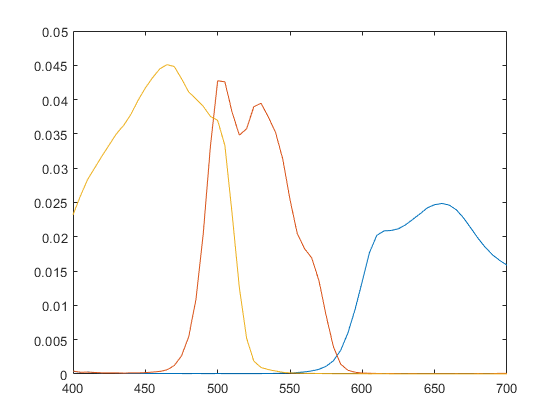

h =   3×1 Line array:

  Line
  Line
  Line


h = plot(L,Ad1)

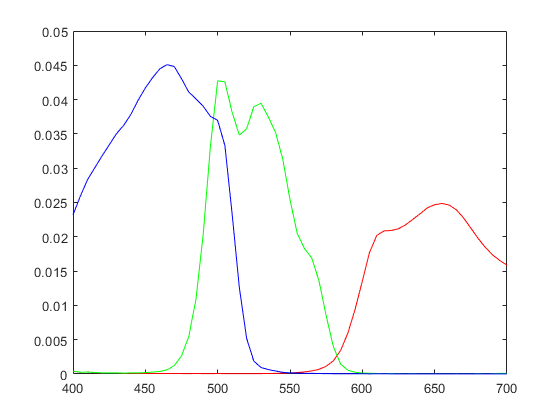

set(h(1),'Color','r');
set(h(2),'Color','g');
set(h(3),'Color','b');

h1 = plot(L,Ad2)

h1 =   3×1 Line array:

  Line
  Line
  Line


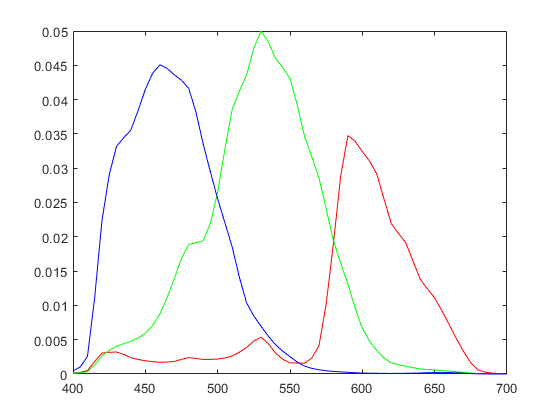

set(h1(1),'Color','r');
set(h1(2),'Color','g');
set(h1(3),'Color','b');


%Based on the sensitive function we think that the results will be different
%but were not sure if it will be noticble by the eye.

%Assignment 1.2
I = load("illum.mat");
S = Ad1;
Chips = load("chips20.mat");
CIED65 = I.CIED65;

Chips = Chips.chips20

Chips =     0.3951    0.4651    0.4948    0.5088    0.5110    0.5107    0.5079    0.5141    0.5149    0.5101    0.5163    0.5165    0.5179    0.5175    0.5210    0.5196    0.5160    0.5162    0.5182    0.5192    0.5279    0.5502    0.5828    0.6081    0.6256    0.6342    0.6315    0.6346    0.6409    0.6605    0.6787    0.6993    0.7147    0.7251    0.7217    0.7270    0.7287    0.7310    0.7284    0.7283    0.7309    0.7292    0.7286    0.7330    0.7318    0.7312    0.7354    0.7370    0.7350    0.7339
    0.2508    0.2665    0.2700    0.2652    0.2604    0.2551    0.2514    0.2494    0.2474    0.2441    0.2411    0.2376    0.2389    0.2386    0.2409    0.2391    0.2327    0.2234    0.2163    0.2122    0.2102    0.2137    0.2138    0.2064    0.1982    0.1881    0.1822    0.1820    0.1907    0.2058    0.2259    0.2440    0.2542    0.2645    0.2751    0.2919    0.3067    0.3210    0.3337    0.3429    0.3443    0.3465    0.3490    0.3491    0.3489    0.3490    0.3485    0.3467    0.3464 

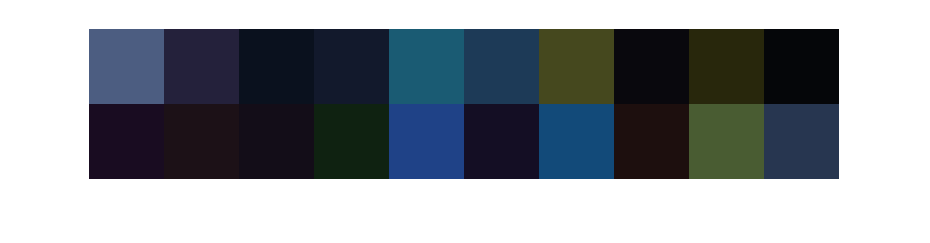

RGB_raw_D65 = Ad1'*(Chips(:,:).*CIED65)';
RGB_raw_D65_2 = Ad2'*(Chips(:,:).*CIED65)';
showRGB(RGB_raw_D65');

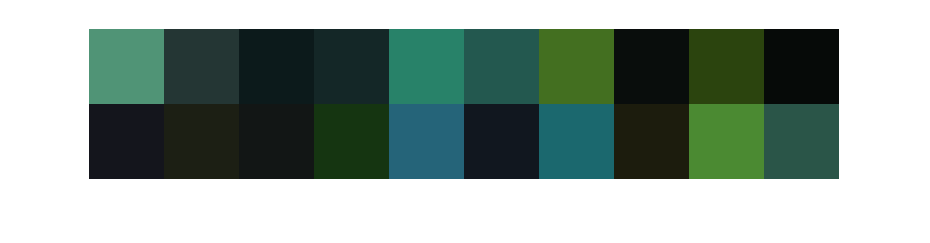

showRGB(RGB_raw_D65_2');

%We can see that the 2nd image has "more" green colors then the first one
%which makes sense if you look at the sensitivite functions since the green
%green sensor apprears stronger. The same can be said for the blue sensor
%in the first image.

%Assignment 2.1
e = ones(1,61);
normalization1 = Ad1'*e'

normalization1 =     0.4635
    0.5646
    0.8585


normalization2 = Ad2'*e'

normalization2 =     0.4726
    0.8747
    0.7420


% We can see that the values of the blue and green channels are higher
% in the same way as before. So for the first image the value of the blue
% channel is higher and for the second image the green channel is higher.

%Assignment 2.2
RGB_cal_D651 = RGB_raw_D65./normalization1

RGB_cal_D651 =     0.6428    0.3014    0.0880    0.1533    0.2163    0.2452    0.5819    0.0744    0.3368    0.0433    0.2098    0.2395    0.1591    0.1259    0.2644    0.1698    0.1510    0.2483    0.6172    0.3261
    0.6472    0.2262    0.1154    0.1730    0.6334    0.4057    0.5001    0.0563    0.2740    0.0438    0.0828    0.1189    0.0915    0.2350    0.4598    0.0950    0.5112    0.1067    0.6405    0.3776
    0.5890    0.2695    0.1377    0.1998    0.5237    0.3977    0.1373    0.0614    0.0560    0.0429    0.1502    0.1032    0.1085    0.0764    0.6166    0.1643    0.5507    0.0653    0.2300    0.3650


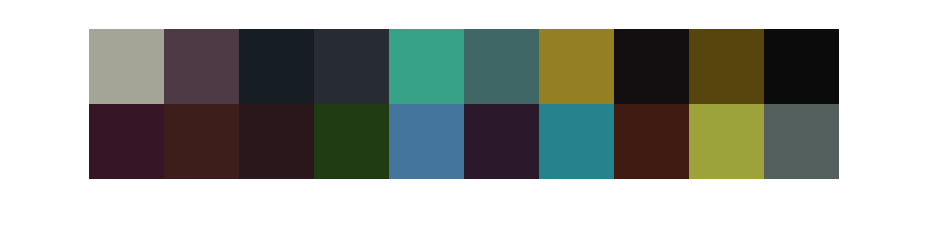

RGB_cal_D652 = RGB_raw_D65_2./normalization2;
showRGB(RGB_cal_D651')

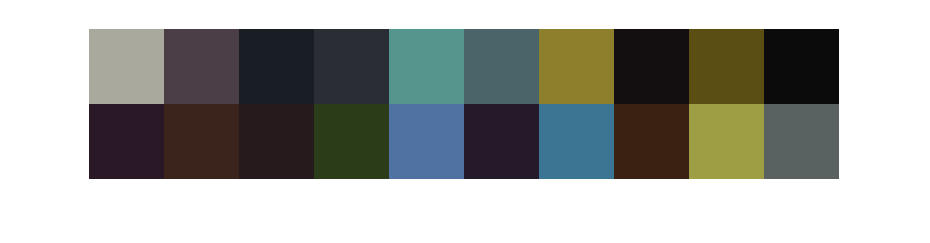

showRGB(RGB_cal_D652')

%Now they are the same

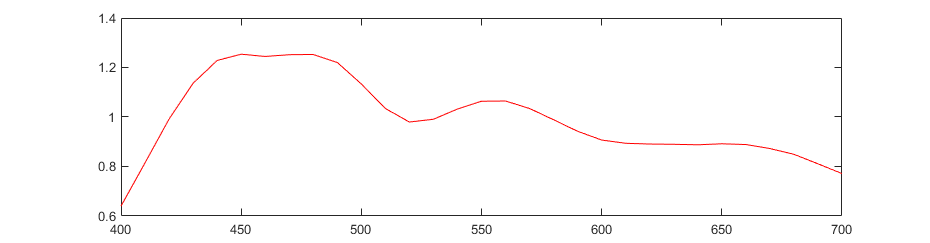

%Assignment 2.3

CIEA = I.CIEA;
plot(L,CIED65,'Color','r')

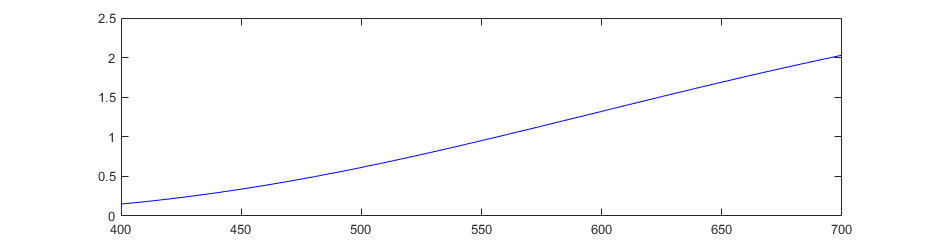


plot(L,CIEA,'Color','b')

%Outdoor is blueish and indoor is warm and raddish/yellowish

%Assignment 2.4
RGB_raw_CIEA = Ad1'*(Chips(:,:).*CIEA)';
RGB_cal_CIEA = RGB_raw_CIEA./normalization1

RGB_cal_CIEA =     1.2120    0.5681    0.1653    0.2878    0.3971    0.4593    1.1028    0.1398    0.6312    0.0814    0.4031    0.4516    0.3003    0.2317    0.4979    0.3243    0.2803    0.4694    1.1652    0.6120
    0.4910    0.1688    0.0841    0.1274    0.4629    0.2984    0.4012    0.0421    0.2365    0.0330    0.0590    0.0946    0.0684    0.1949    0.3252    0.0676    0.3584    0.0876    0.5025    0.2838
    0.2105    0.0928    0.0479    0.0695    0.1988    0.1438    0.0649    0.0214    0.0229    0.0152    0.0488    0.0364    0.0373    0.0297    0.2140    0.0539    0.2042    0.0241    0.1034    0.1294


RGB_raw_CIEA2 = Ad2'*(Chips(:,:).*CIEA)';
RGB_cal_CIEA2 = RGB_raw_CIEA2./normalization2

RGB_cal_CIEA2 =     0.9149    0.4195    0.1285    0.2228    0.4009    0.3786    0.8100    0.1056    0.5172    0.0628    0.2394    0.3347    0.2148    0.2293    0.3811    0.2060    0.2589    0.3419    0.8915    0.4788
    0.5344    0.1951    0.0872    0.1361    0.4439    0.3018    0.4416    0.0483    0.2882    0.0359    0.0708    0.1243    0.0816    0.2109    0.3189    0.0771    0.3287    0.1190    0.5363    0.3026
    0.2426    0.1028    0.0528    0.0771    0.2256    0.1619    0.0926    0.0241    0.0411    0.0172    0.0522    0.0425    0.0416    0.0442    0.2341    0.0577    0.2257    0.0303    0.1364    0.1472


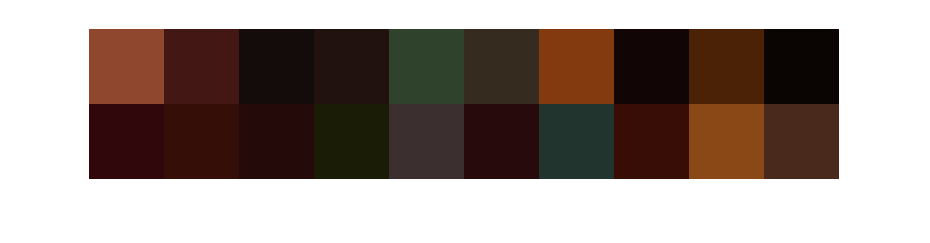

showRGB(RGB_raw_CIEA');

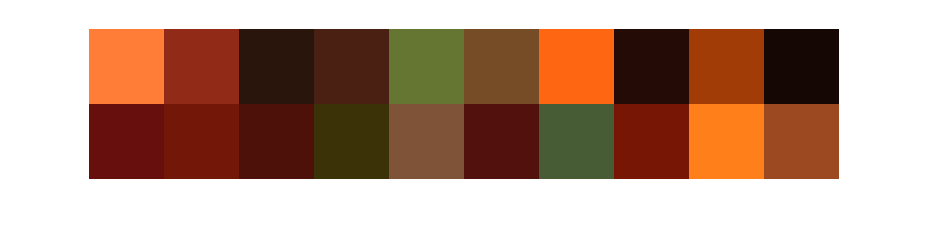

showRGB(RGB_cal_CIEA');

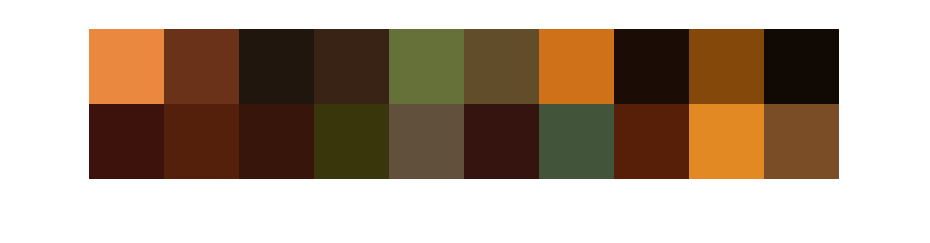

showRGB(RGB_cal_CIEA2');

% They both AD and Ad2 appear more reddish under the light source CIEA
% which we think makes sense since it has a higher value in the red
% wavelenght

%Assignment 2.5
ED65 = e.*CIED65

ED65 =     0.6400    0.7275    0.8149    0.9034    0.9919    1.0642    1.1364    1.1824    1.2285    1.2411    1.2537    1.2492    1.2446    1.2482    1.2517    1.2522    1.2527    1.2365    1.2204    1.1769    1.1334    1.0839    1.0343    1.0070    0.9797    0.9853    0.9909    1.0116    1.0323    1.0480    1.0636    1.0642    1.0647    1.0495    1.0343    1.0116    0.9888    0.9656    0.9423    0.9246    0.9069    0.9004    0.8938    0.8923    0.8908    0.8902    0.8897    0.8887    0.8877    0.8897


EA = e.*CIEA

EA =     0.1506    0.1658    0.1810    0.1980    0.2150    0.2338    0.2526    0.2733    0.2939    0.3164    0.3388    0.3630    0.3872    0.4131    0.4390    0.4665    0.4940    0.5231    0.5521    0.5825    0.6130    0.6448    0.6765    0.7094    0.7423    0.7763    0.8103    0.8452    0.8801    0.9158    0.9515    0.9878    1.0240    1.0608    1.0976    1.1347    1.1719    1.2092    1.2466    1.2840    1.3215    1.3589    1.3962    1.4335    1.4707    1.5077    1.5446    1.5812    1.6178    1.6539


light_normalization1 = Ad1'*ED65'

light_normalization1 =     0.4069
    0.5976
    0.9756


light_normalization2 = Ad1'*EA'

light_normalization2 =     0.7653
    0.4412
    0.3437


RGB_light_D65 = RGB_raw_D65./light_normalization1

RGB_light_D65 =     0.7323    0.3434    0.1003    0.1747    0.2465    0.2794    0.6630    0.0848    0.3837    0.0493    0.2390    0.2729    0.1812    0.1435    0.3013    0.1935    0.1720    0.2829    0.7032    0.3716
    0.6115    0.2137    0.1090    0.1635    0.5984    0.3833    0.4725    0.0532    0.2589    0.0414    0.0782    0.1124    0.0865    0.2221    0.4345    0.0898    0.4831    0.1008    0.6051    0.3568
    0.5183    0.2372    0.1212    0.1758    0.4608    0.3499    0.1208    0.0540    0.0493    0.0377    0.1322    0.0908    0.0955    0.0672    0.5425    0.1446    0.4846    0.0575    0.2024    0.3212


RGB_light_CIEA = RGB_raw_CIEA./light_normalization2

RGB_light_CIEA =     0.7340    0.3441    0.1001    0.1743    0.2405    0.2782    0.6679    0.0847    0.3823    0.0493    0.2441    0.2735    0.1819    0.1403    0.3016    0.1964    0.1697    0.2843    0.7057    0.3706
    0.6283    0.2161    0.1077    0.1630    0.5924    0.3819    0.5134    0.0539    0.3027    0.0422    0.0755    0.1210    0.0875    0.2494    0.4162    0.0864    0.4586    0.1121    0.6430    0.3632
    0.5257    0.2318    0.1195    0.1737    0.4966    0.3590    0.1620    0.0535    0.0571    0.0380    0.1218    0.0909    0.0931    0.0741    0.5346    0.1347    0.5100    0.0602    0.2583    0.3231


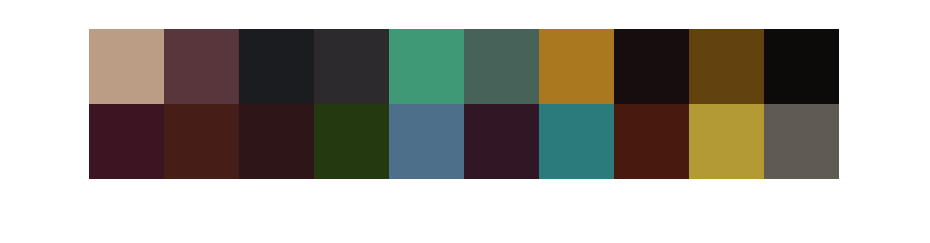

showRGB(RGB_light_D65')

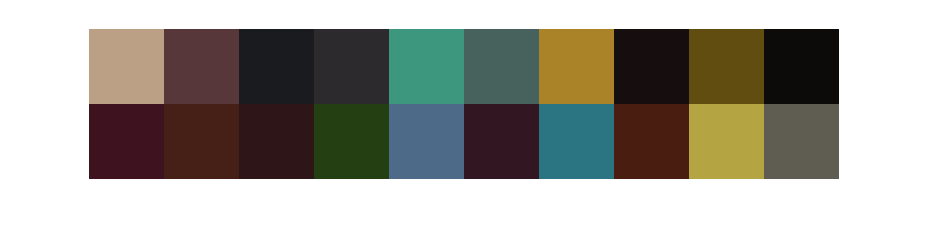

showRGB(RGB_light_CIEA')


%Now they look the same

%Assignment 3.1 
CMFs = load("xyz.mat");
xyz = CMFs.xyz;
CMF = xyz'*ED65'

CMF =    21.0809
   21.5237
   25.3801


XYZZ_D651_ref = xyz'*(Chips(:,:).*ED65)'

XYZZ_D651_ref =    14.3149    6.2723    2.2246    3.6794    8.0181    6.7734   11.1639    1.5393    7.6876    0.9837    3.1850    4.5741    2.9477    4.1232    7.4380    2.9775    5.7739    4.4971   12.7214    7.7820
   14.4780    5.5867    2.2511    3.6194   10.6112    7.6038   12.3079    1.3867    8.2380    0.9768    2.2476    3.8944    2.4576    5.4037    7.7731    2.2748    7.5224    3.8263   14.5673    8.0271
   13.1313    6.1112    3.1156    4.5058   10.8246    8.7172    2.1528    1.3832    1.1754    0.9489    3.5550    2.2940    2.4621    1.6188   14.1482    3.8746   11.8035    1.4189    3.8252    8.1377


%XYZZ_D651_ref = XYZZ_D651_ref.*(100./XYZZ_D651_ref(2,:)) %normalize

%Assignment 3.2
load("M_XYZ2RGB.mat")
invers_M = inv(M_XYZ2RGB);
XYZZ_D651= invers_M*RGB_cal_D651

XYZZ_D651 =    60.2807   25.3819   10.2413   16.1157   41.0190   31.7965   44.3620    6.1891   24.7008    4.1275   14.3237   15.9949   11.7908   14.9757   38.4732   13.3662   34.4431   15.2347   52.5084   33.5394
   64.2045   24.5310   11.1173   17.0764   53.6754   37.1004   49.1332    6.0519   27.1619    4.3659   11.4666   14.3452   10.7111   20.0372   42.9575   11.5931   43.7467   13.3826   60.5896   36.5763
   64.9263   28.8888   14.6345   21.3417   57.7292   43.0964   20.1329    6.6462    9.2427    4.6809   15.6652   11.6850   11.7060   10.3007   64.5800   17.0730   58.7151    7.9590   30.6806   39.8123


%XYZZ_D651= XYZZ_D651.*(100./XYZZ_D651(2,:)) %normalize

for i = 1:20
    result(i) = labDiff(XYZZ_D651(:,i), XYZZ_D651_ref(:,i));
end

M_res = max(result)

M_res = 41.3390

m_res = mean(result)

m_res = 28.8194

min_res = min(result)

min_res = 16.3443


% This is a bad result! mean values 18 is so high that we will se
% differences in most of the colors.

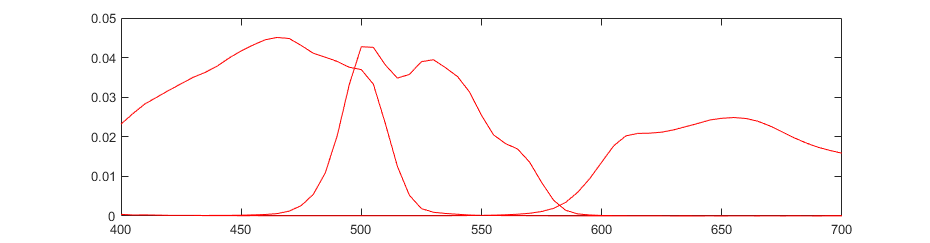

%Assignment 3.3
plot(L,Ad1,'Color','r')

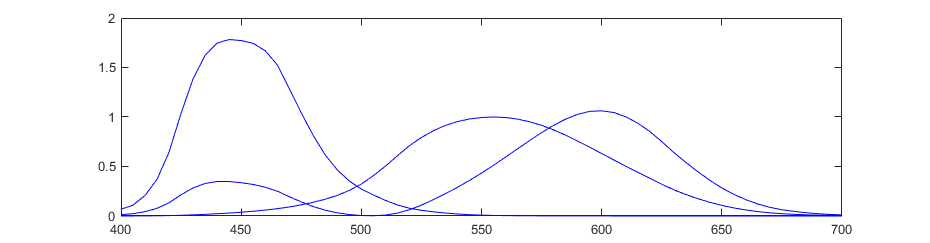


plot(L,xyz','Color','b')


%The standard model is smoother. This makes sence since it shows the
%overall trend.

%Assignment 3.4
D = RGB_cal_D651';
C = XYZZ_D651_ref;
A = pinv(D)*C';
estimate = (D*A)';
for i = 1:20
    result34(i) = labDiff(C(:,i), estimate(:,i));
end
M_res = max(result34)

M_res = 3.4985

m_res = mean(result34)

m_res = 1.3054

min_res = min(result34)

min_res = 0.3728


% This is good result! the human eye should have problem seeing differences
% in colors.

%Assignment 3.5
A2 = Optimize_poly(RGB_cal_D651,XYZZ_D651); %11x3
pr = Polynomial_regression(RGB_cal_D651,A2)

pr =    60.2807   25.3819   10.2413   16.1157   41.0190   31.7965   44.3620    6.1891   24.7008    4.1275   14.3237   15.9949   11.7908   14.9757   38.4732   13.3662   34.4431   15.2347   52.5084   33.5394
   64.2045   24.5310   11.1173   17.0764   53.6754   37.1004   49.1332    6.0519   27.1619    4.3659   11.4666   14.3452   10.7111   20.0372   42.9575   11.5931   43.7467   13.3826   60.5896   36.5763
   64.9263   28.8888   14.6345   21.3417   57.7292   43.0964   20.1329    6.6462    9.2427    4.6809   15.6652   11.6850   11.7060   10.3007   64.5800   17.0730   58.7151    7.9590   30.6806   39.8123



for i = 1:20
    result35(i) = labDiff(XYZZ_D651_ref(:,i), pr(:,i));
end

M_res = max(result35)

M_res = 41.3390

m_res = mean(result35)

m_res = 28.8194

min_res = min(result35)

min_res = 16.3443


% Same result as in 3.2. weird?